## **Báo cáo sơ bộ nhóm 2**

**Đề tài: Nhận dạng biển số**

# **I Tổng Quát**

Lĩnh vực xử lí ảnh số, bao gồm xử lí, phân tích và nhận biết tự động bằng máy tính, đã và đang có sự phát triển mạnh mẽ trong cả lý thuyết và các ứng dụng thực tế. Xử lí ảnh được ứng trong nhiều lĩnh vực quan trọng như: Viễn thông, truyền thông, chụp ảnh y tế, sinh học, khoa học vật liệu, rô-bốt, sản xuất, các hệ thống cảm biến thống minh, tự động điểu khiển, đồ họa, in ấn... Sự phát triển mạnh này có thể được thấy rõ qua số lượng các bài báo, báo cáo khoa học về xử lí ảnh hàng năm cũng như qua số lượng các đầu sách viết về xử lí ảnh

Như chúng ta đã biết, ngày nay phương tiện giao thông ngày càng tăng cáo đặc biệt là số lượng ô tô tăng mạnh mẽ so với nhiều năm về trước. Vì vậy vấn đề quản lý giao thông, bảo đảm an ninh, thu phí giao thông... đòi hỏi và cần thiết có sự hỗ trợ của khoa học kỹ thuật. Một trong những sự hỗ trợ đầy hiệu quả đó là làm sao giúp những người quản lý nhận dạng biển sô xe được dễ dàng, nhanh chóng và thuật lợi nhất.

Nhận dạng biển số xe trở thành một ứng dụng hữu ích, được đưa vào trong những lĩnh vực như: quản lí giao thông, kiểm tra an ninh, thu phí giao thông, trạm gác cổng, quản lý các bãi giữ xe một cách tự động, xử lí phạt nguội phương tiện đi lại.

# **II Các công cụ, phương pháp sử dụng**

#### 1.**Mô tả dữ liệu**

Bộ dữ liệu được lấy từ Kaggle, chứa khoảng 433 ảnh chụp các ô tô và biển số có định dạng png.

#### 2.**Công cụ**

Công cụ được sử dụng cho bài toán là MATLAB và sử dụng mô hình YOLOv2 của MATLAB

#### 3.Phương pháp thực hiện.

**3.1 Tiền xử lí dữ liệu**

**3.1.1 Resize Image**

Đâu tiên chúng ta sẽ resize khó ảnh về kích thước 416x416 .Tại sao chúng ta lại chọn 416x416 vì đây chính là kích thược tốt nhất cho mô hình YOLOv2 để training và cho ra được kêt quả cao nhất.

srcFiles = dir(fullfile('dataset\images',"*.png"));
    for i = 1 : length(srcFiles)
        filename = ['dataset\images\',srcFiles(i).name];
        im = imread(filename);
        k=imresize(im,[416,416]);
        newfilename=['dataset\newimages\' ,srcFiles(i).name];
        imwrite(k,newfilename,'png');
    end

**3.1.2 Chia kho dữ liệu**

Chúng ta sẽ chia kho dữ liệu ra làm 3 phần:

- 60% cho training mô hình

- 20% cho test

- 20% cho validation

files = dir(fullfile('dataset\newimages',"*.png"));
    N = length(files);
    rd=randperm(N);
    tf=rd<(0.6*N);
    tf1 = rd>=(0.6*N) & rd<(0.8*N);
    mkdir testResized;
    mkdir trainResized;
    mkdir valResized1;
    
    for i=1:length(tf)
        files_re = files(i).name;
        if tf(i) == 1
            copyfile (fullfile('dataset\newimages\',files_re),'trainResized')
        elseif tf1(i) == 1
             copyfile (fullfile('dataset\newimages\',files_re),'trainResized')
        else
            copyfile (fullfile('dataset\newimages\',files_re),'valResized1')
        end
    end

**3.1.3 Tạo Groud Truth**

Groud Truth là một đối tượng chứa thông tin về dữ liệu nguồn, các nhãn đã được đánh, các chú thích của nhãn.Trong Matlab chúng ta có thể dùng Image Labeler bằng cách dùng câu lệnh imageLabeler để gán nhán dữ liệu . Trong bài toán này chúng ta sẽ gán nhán cho 3 tập khác nhau: training, test, validation tương ứng là 3 file grouth

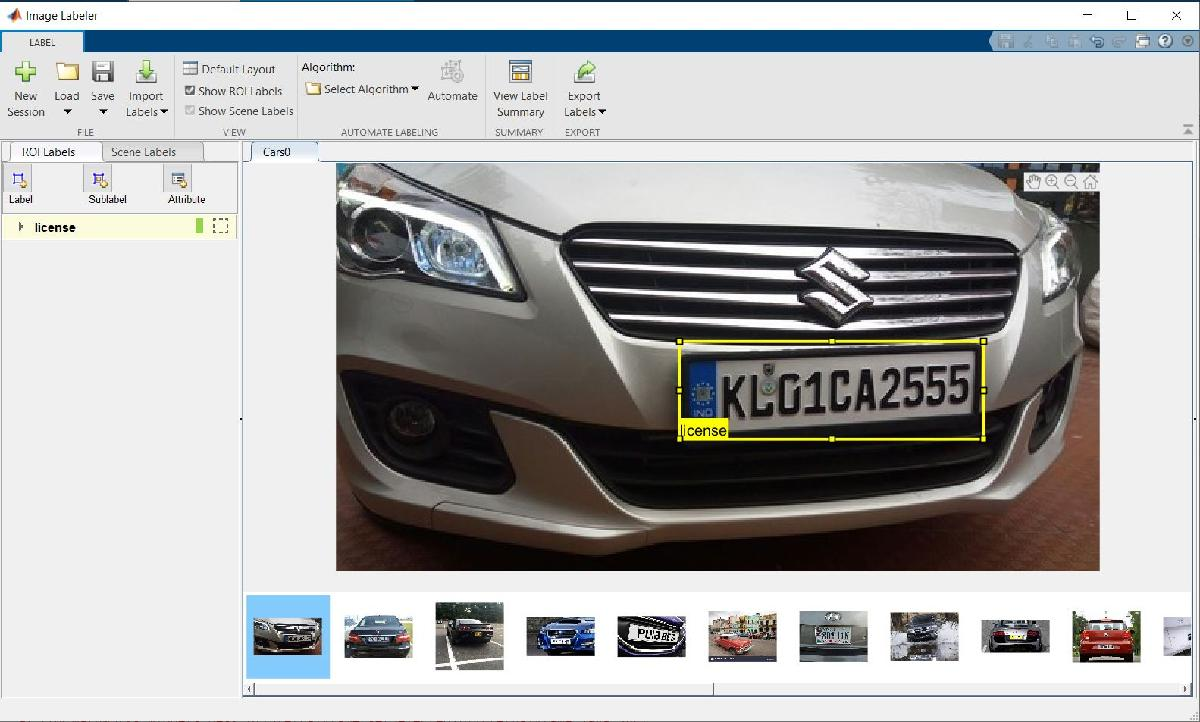

**3.1.4 Chuyển đổi gTruth object thành Training, Validation và Testing Data**

load('gTruthTrain.mat');
gTruthTrain = selectLabels(gTruth,'license');
if ~isfolder(fullfile("TrainingData"))
    mkdir TrainingData
end
addpath('TrainingData');
trainingData = objectDetectorTrainingData(gTruthTrain,'SamplingFactor',1,...
    'WriteLocation','TrainingData');
trainingData(1:4,:)

load('gTruthTest.mat');
gTruthTest = selectLabels(gTruth,'license');
if ~isfolder(fullfile("TestData"))

ans = 4×2 table
                                  imageFilename                                    license   
    _________________________________________________________________________    ____________

    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\trainResized\Cars2.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\trainResized\Cars3.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\trainResized\Cars4.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\trainResized\Cars6.png'}    {1×4 double}


    mkdir TestData
end
addpath('TestData');
testData = objectDetectorTrainingData(gTruthTest,'SamplingFactor',1,...
    'WriteLocation','TestData');

testData(1:4,:)

load('gTruthVal.mat');
gTruthVal = selectLabels(gTruth,'license');
if ~isfolder(fullfile("ValData"))
    mkdir ValData

ans = 4×2 table
                                  imageFilename                                    license   
    _________________________________________________________________________    ____________

    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\testResized\Cars9.png' }    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\testResized\Cars12.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\testResized\Cars13.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\testResized\Cars15.png'}    {1×4 double}


end
addpath('ValData');
valData = objectDetectorTrainingData(gTruthVal,'SamplingFactor',1,...
    'WriteLocation','ValData');

valData(1:4,:)

#### 3.2 Design and Train YOLOv2 in MATLAB

**3.2.1 Design YOLOv2 network layers **

Trong mô hình này, chúng ta thiết kế từng lớp mô hình YOLOv2 tùy chỉnh. Mô hình bắt đầu bởi một lớp đầu vào. Sau đó, mạng con detection chứa một loạt các lớp Conv, Batch Norm và ReLu, theo sau là các đối tượng yolov2TransformLayer và yolov2OutputLayer tương ứng. yolov2TransformLayer chuyển đổi đầu ra CNN thô thành một dạng cần thiết để tạo ra các phát hiện đối tượng. yolov2OutputLayer xác định các tham số anchor box và thực hiện hàm loss  để đào tạo trình phát hiện.

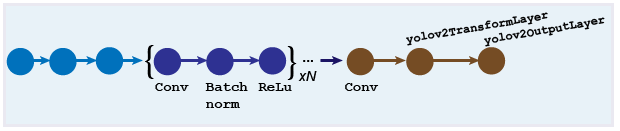

Hàm imageInputLayer được sử dụng để xác định lớp đầu vào hình ảnh với kích thước hình ảnh tối thiểu (128x128x3). 

inputLayer = imageInputLayer([128 128 3],'Name','input','Normalization','none');

Đặt kích thước bộ lọc lớp tích chập thành [3 3]. Kích thước này là phổ biến trong kiến trúc CNN. FilterSize xác định kích thước (chiều cao & chiều rộng) của các vùng cục bộ mà các nơ-ron kết nối trong đầu vào.

filterSize = [3 3];

ans = 4×2 table
                                 imageFilename                                    license   
    ________________________________________________________________________    ____________

    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\valResized\Cars11.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\valResized\Cars18.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\valResized\Cars21.png'}    {1×4 double}
    {'C:\Users\nguye\Documents\thuchanhtinhtoan\test\valResized\Cars25.png'}    {1×4 double}


Đối với các lớp ở giữa, chúng ta sử dụng một loạt Convolution2dLayer,Batch Normalization Layer, Lớp RelU và Max Pooling layer. Tương tự như các mô hình phân loại khác như mô hình VGG, chúng ta đã nhân đôi số kênh (Kích thước bộ lọc) sau mỗi bước tổng hợp. Chúng tôi đã sử dụng chuẩn hóa hàng loạt để ổn định quá trình đào tạo, tăng tốc độ hội tụ và chuẩn hóa mô hình.

middleLayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name','conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name','conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
    ];

**3.2.2 Tạo biểu đồ lớp cho mạng yolov2.**

Kết hợp các lớp ban đầu và giữa và chuyển đổi thành một đối tượng biểu đồ lớp để thao tác các lớp

lgraph = layerGraph([inputLayer; middleLayers]);

Tính toán số lượng Lớp dựa trên dữ liệu Đầu vào.

numClasses = size(trainingData,2)-1;

**3.2.3 Xác định Anchor box**

Các anchor box là một tập hợp các hộp giới hạn được xác định trước có chiều cao và chiều rộng nhất định. Các hộp này được xác định để nắm bắt tỷ lệ và tỷ lệ khung hình của các lớp đối tượng cụ thể mà ta muốn phát hiện và thường được chọn dựa trên kích thước đối tượng trong bộ dữ liệu đào tạo của ta. Chúng ta có thể xác định một số anchor box, mỗi hộp cho một kích thước đối tượng khác nhau. Việc sử dụng các anchor box cho phép mạng phát hiện nhiều đối tượng, đối tượng có tỷ lệ khác nhau và đối tượng chồng chéo

Anchors = [37 63
    64 88
    20 33
    43 115
    56 94];

**3.2.4 Kết hợp mạng YOLOv2**

Hàm yolov2Layers tạo mạng YOLO v2, đại diện cho kiến trúc mạng cho trình phát hiện đối tượng YOLO v2.'relu_4' là lớp trích xuất tính năng , Các tính năng được trích xuất từ lớp này được cung cấp làm đầu vào cho mạng con phát hiện đối tượng YOLO v2.

lgraph = yolov2Layers([128 128 3],numClasses,Anchors,lgraph,'relu_4');
analyzeNetwork(lgraph);

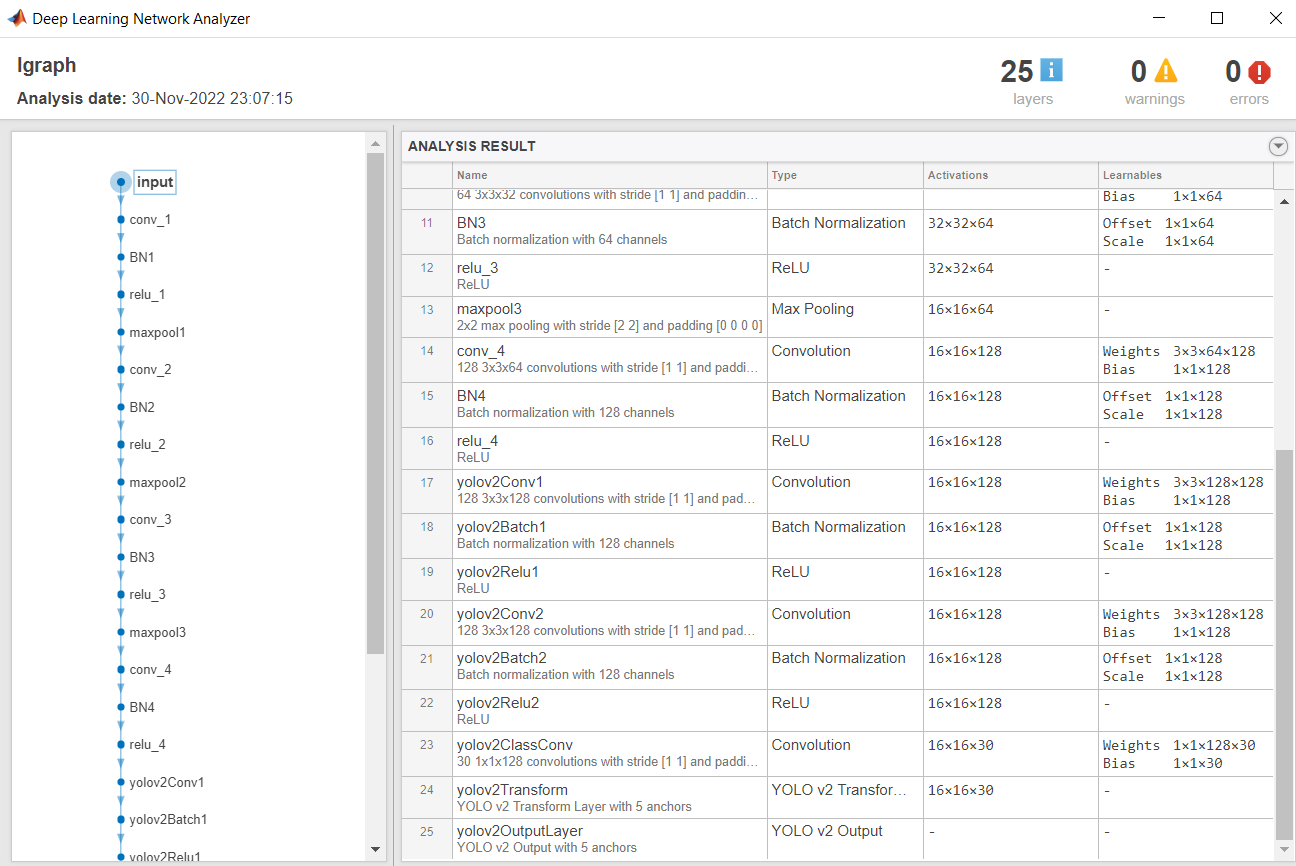

**3.2.5 Huấn luyện**

Chúng ta đào tạo mạng với bộ giải - giảm dần độ dốc ngẫu nhiên cho 80 epoch với hệ học ban đầu là 0,001 và mini-batch size là 16. 

ExecutEnvironment xác định tài nguyên phần cứng cho mạng đào tạo.

DispatchInBackground chỉ được sử dụng khi đào tạo song song hoặc môi trường đa GPU.

rng(0);
options = trainingOptions('sgdm', ...
        'InitialLearnRate',0.001, ...
        'Verbose',true,'MiniBatchSize',16,'MaxEpochs',80,...
        'Shuffle','every-epoch','VerboseFrequency',50, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment','auto');

Gọi hàm đào tạo YOLOv2 - trainYOLOv2ObjectDetector

[detectorYolo2, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* license

Checking training data...done.
Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         8.00 |         64.0 |          0.0010 |
|       4 |          50 |       00:00:33 |         1.22 |          1.5 |          0.0010 |
|       7 |         100 |       00:01:04 |         1.26 |          1.6 |          0.0010 |
|      10 |         150 |       00:01:35 |         0.89 |          0.8 |          0.0010 |
|      13 |         200 |       00:02:06 |         0.93 |     

save detectorYolo2

**3.2.6 Nhận dạng biển số **

Tạo một bảng để giữ kết quả

results = table('Size',[height(testData) 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores', 'Labels'});  
for i = 1:height(testData)

    % Read the image
    I = imread(testData.imageFilename{i});
    
    % Run the detector.
    [bboxes,scores,labels] = detect(detectorYolo2,I);
    
    %         
    
    % Collect the results in the results table
    results.Boxes{i} = floor(bboxes);
    results.Scores{i} = scores;
    results.Labels{i} = labels;

end



**3.2.7 Đánh giá**

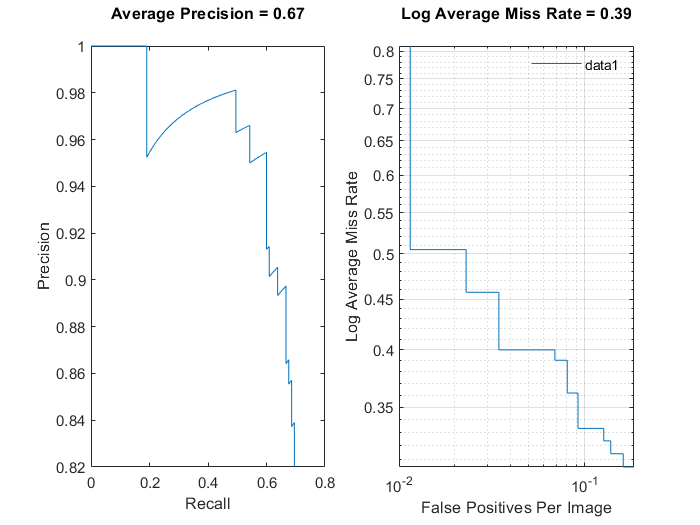

threshold =0.2;
[ap, recall, precision] = evaluateDetectionPrecision(results, testData(:,2:end),threshold);
[am,fppi,missRate] = evaluateDetectionMissRate(results, testData(:,2:end),threshold);

subplot(1,2,1);

plot(recall,precision);
xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.2f\n', ap))
subplot(1,2,2);
loglog(fppi, missRate);
xlabel('False Positives Per Image');
ylabel('Log Average Miss Rate');
title(sprintf('Log Average Miss Rate = %.2f\n', am))
legend('Location', 'best');
legend('boxoff')
grid on

**Đánh giá: **Độ chính xác chung bình 0.67 tỉ lệ bỏ sót 0.39


img = imread('C:\Users\nguye\Documents\thuchanhtinhtoan\test\dataset\images\Cars159.png'); 
[bboxes,scores] = detect(detectorYolo2,img);

 for i = 1:length(scores)
     scores(i)
     annotation = sprintf('Confidence = %.4f',scores(i));
     bboxes(i,:);
     img = insertObjectAnnotation(img, 'rectangle',bboxes(i,:),annotation);
 end

ans = single
0.9361

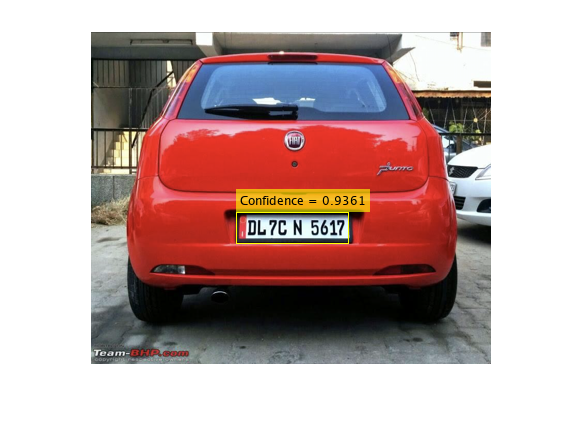


 figure
 imshow(img);

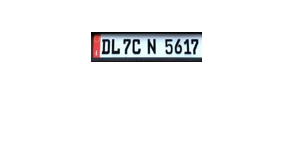


x1 = bboxes(1,1)+1;
y1 = bboxes(1,2)+1;
x2 = bboxes(1,3)+x1-3;
y2 = bboxes(1,4)+y1-3;    
imgcrop = img(y1:y2, x1:x2,1:3);
imshow(imgcrop)

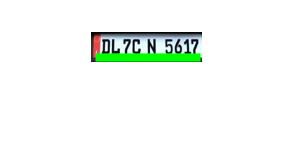

m=imadjust(rgb2gray(imgcrop));
[r c]=size(imgcrop);
BW = edge(m,'canny');
% imshow(BW);
[H,T,R] = hough(BW);
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
P  = houghpeaks(H,1,'threshold',ceil(0.9*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');
lines = houghlines(BW,T,R,P,'FillGap',0.8*c,'MinLength',40);
figure, imshow(imgcrop), hold on
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',5,'Color','green');
end

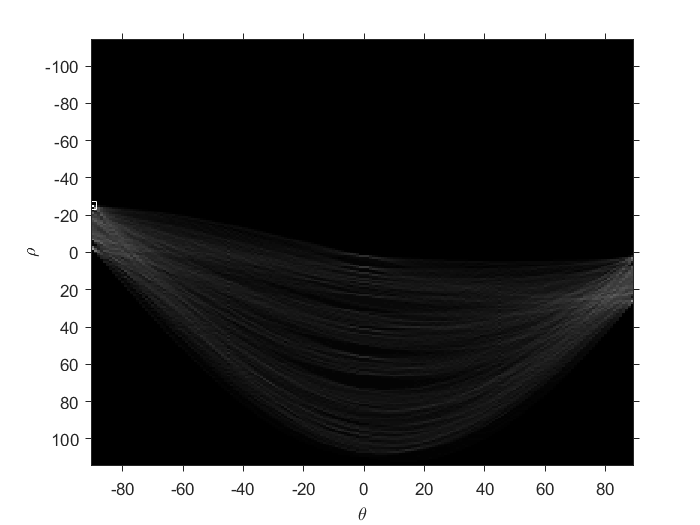

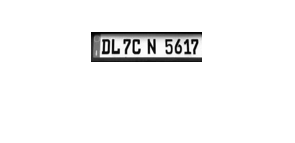

figure;
if(lines.theta<0)
imgrotate=imrotate_white(m,(90-abs(lines.theta)));
else
    imgrotate=(imrotate_white(m,lines.theta-90));
end
%imshow(imgrotate);
imshow(imgrotate);

[~,long]=size(imgrotate);
scale = round(500/long)

scale = 5

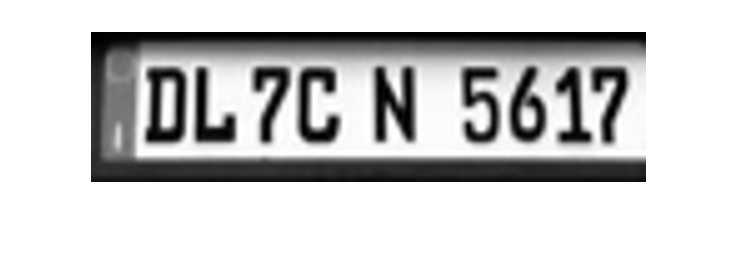

figure
imgresize = imresize(imgrotate,scale,'Method',"bicubic");
imshow(imgresize)

threshold = graythresh(imgresize)-0.1

threshold = 0.4373

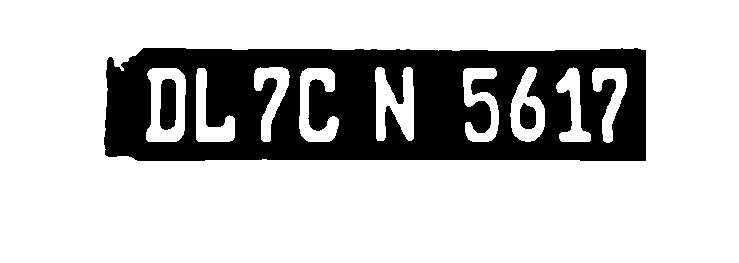

imgresize =~im2bw(imgresize,threshold);
imgresize = bwareaopen(imgresize,30);
figure
imshow(imgresize)

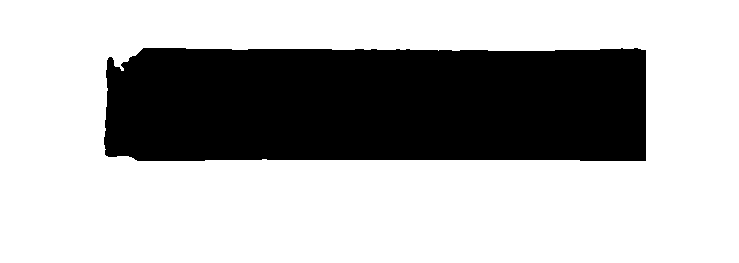

[~,cc]=size(imgresize);
if cc>200
    picture1=bwareaopen(imgresize,3000);
else
picture1=bwareaopen(imgresize,2500);
end
figure,imshow(picture1)

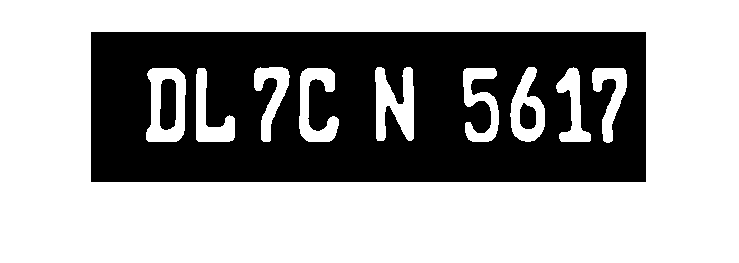

picture2=imgresize-picture1;
picture2=bwareaopen(picture2,200);
figure,imshow(picture2);

text = ocr(picture2).Text

text =     'DL7C N 5617
     
     '


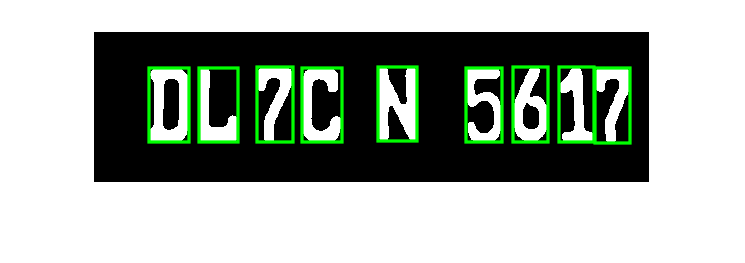

picture2=bwareaopen(picture2,200);
figure,imshow(picture2)

[L,Ne]=bwlabel(picture2);
propied=regionprops(L,'BoundingBox');
hold on
pause(1)
for n=1:size(propied,1)
  rectangle('Position',propied(n).BoundingBox,'EdgeColor','g','LineWidth',2);
end
hold off

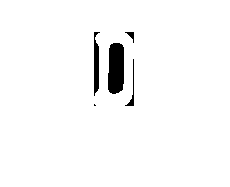

ans =     'ill
     
     '


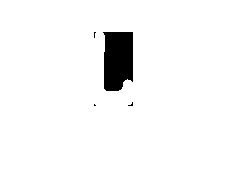


ans =

  0×0 empty char array



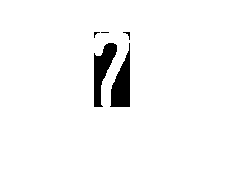


ans =

  0×0 empty char array



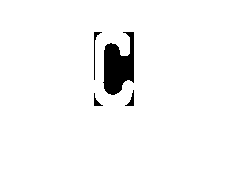


ans =

  0×0 empty char array



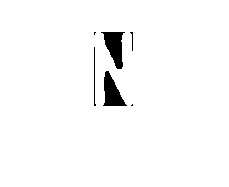


ans =

  0×0 empty char array



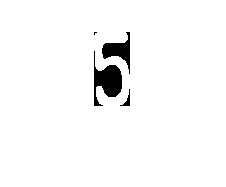


ans =

  0×0 empty char array



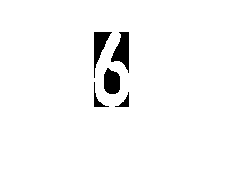


ans =

  0×0 empty char array



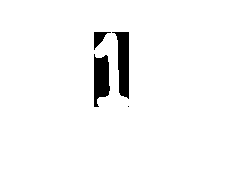


ans =

  0×0 empty char array



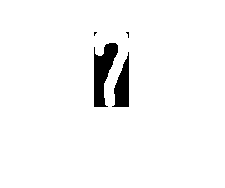


ans =

  0×0 empty char array




figure
final_output=[];
t=[];
for n=1:Ne
  [r,c] = find(L==n);
  n1=imgresize(min(r):max(r),min(c):max(c));
  figure
  imshow(n1)
  ocr(n1).Text
  n1=imresize(n1,[42,24]);
  
  pause(0.2)
  x=[ ];

totalLetters=size(imgfile,2);

 for k=1:totalLetters
    
    y=corr2(imgfile{1,k},n1);
    x=[x y];
    
 end
 t=[t max(x)];
 if max(x)>.45
 z=find(x==max(x));
 out=cell2mat(imgfile(2,z));

final_output=[final_output out];
end
end

final_output

final_output = '0L7CN55t7'

function rotated_image = imrotate_white(image, rot_angle_degree)
    RA = imref2d(size(image));    
    tform = affine2d([cosd(rot_angle_degree)    -sind(rot_angle_degree)     0; ...
                      sind(rot_angle_degree)     cosd(rot_angle_degree)     0; ...
                      0                          0                          1]);
      Rout = images.spatialref.internal.applyGeometricTransformToSpatialRef(RA,tform);
      Rout.ImageSize = RA.ImageSize;
      xTrans = mean(Rout.XWorldLimits) - mean(RA.XWorldLimits);
      yTrans = mean(Rout.YWorldLimits) - mean(RA.YWorldLimits);
      Rout.XWorldLimits = RA.XWorldLimits+xTrans;
      Rout.YWorldLimits = RA.YWorldLimits+yTrans;
      rotated_image = imwarp(image, tform, 'OutputView', Rout, 'interp', 'cubic', 'fillvalues', 255);
end